regionLinearIndices = struct();
% Create new structure for storing coordinates
regionCoordinates = struct();

% Swap x and y coordinates if needed
swappedCentroids = [centroids(:, 2), centroids(:, 1)]; % Swap x and y to match mask orientation

for i = 1:numRegions
    sanitizedRegionName = strrep(labels{i}, '-', '_'); % Sanitize region names
    if ~isempty(swappedCentroids(i, :)) && ~any(isnan(swappedCentroids(i, :)))
        roundedCentroid = round(swappedCentroids(i, :));
        
        % Create offsets for 3x3 region
        [offsetY, offsetX] = meshgrid(-1:1, -1:1);
        offsetY = offsetY(:);
        offsetX = offsetX(:);
        
        % Initialize arrays to store indices and coordinates for this region
        regionIndices = [];
        regionXY = zeros(length(offsetY), 2); % Store [y, x] coordinates
        
        % Generate all 9 coordinates
        for j = 1:length(offsetY)
            newY = roundedCentroid(1) + offsetY(j);
            newX = roundedCentroid(2) + offsetX(j);
            
            % Clip coordinates to valid ranges
            newY = max(1, min(size(brainMaskStruct.WarpData.brainMask, 1), newY));
            newX = max(1, min(size(brainMaskStruct.WarpData.brainMask, 2), newX));
            
            % Store the coordinates
            regionXY(j,:) = [newY, newX];
            
            % Convert to linear index
            linearIndex = sub2ind_brainMask([newY, newX], brainMaskStruct);
            
            if ~isnan(linearIndex) && ~isempty(linearIndex)
                regionIndices = [regionIndices; linearIndex];
            end
        end
        
        if ~isempty(regionIndices)
            regionLinearIndices.(sanitizedRegionName) = unique(regionIndices);
            regionCoordinates.(sanitizedRegionName) = regionXY; % Store all coordinates
        end
    end
end

% Display results
disp('Region Linear Indices:');

Region Linear Indices:


disp(regionLinearIndices);

         MOp1: [9×1 double]
         MOs1: [9×1 double]
       SSp_n1: [9×1 double]
     SSp_bfd1: [9×1 double]
      SSp_ll1: [9×1 double]
       SSp_m1: [9×1 double]
      SSp_ul1: [9×1 double]
      SSp_tr1: [9×1 double]
      SSp_un1: [9×1 double]
         SSs1: [9×1 double]
        AUDd1: [9×1 double]
        AUDp1: [9×1 double]
       AUDpo1: [9×1 double]
       VISal1: [9×1 double]
       VISam1: [9×1 double]
        VISl1: [9×1 double]
        VISp1: [9×1 double]
       VISpm1: [9×1 double]
       VISli1: [9×1 double]
        ACAd1: [9×1 double]
          PL1: [9×1 double]
      RSPagl1: [9×1 double]
        RSPd1: [9×1 double]
        RSPv1: [9×1 double]
        VISa1: [9×1 double]
       VISrl1: [9×1 double]
         TEa1: [9×1 double]
    allcortex: [9×1 double]



disp('Region Coordinates (y,x):');

Region Coordinates (y,x):


disp(regionCoordinates);

         MOp1: [9×2 double]
         MOs1: [9×2 double]
       SSp_n1: [9×2 double]
     SSp_bfd1: [9×2 double]
      SSp_ll1: [9×2 double]
       SSp_m1: [9×2 double]
      SSp_ul1: [9×2 double]
      SSp_tr1: [9×2 double]
      SSp_un1: [9×2 double]
         SSs1: [9×2 double]
        AUDd1: [9×2 double]
        AUDp1: [9×2 double]
       AUDpo1: [9×2 double]
       VISal1: [9×2 double]
       VISam1: [9×2 double]
        VISl1: [9×2 double]
        VISp1: [9×2 double]
       VISpm1: [9×2 double]
       VISli1: [9×2 double]
        ACAd1: [9×2 double]
          PL1: [9×2 double]
      RSPagl1: [9×2 double]
        RSPd1: [9×2 double]
        RSPv1: [9×2 double]
        VISa1: [9×2 double]
       VISrl1: [9×2 double]
         TEa1: [9×2 double]
    allcortex: [9×2 double]




% Rest of visualization code remains the same...

upDurations = struct();
downDurations = struct();
upMeanDurations = struct();
downMeanDurations = struct();

for i = 1:numRegions
    regionName = labels{i};
    sanitizedRegionName = strrep(regionName, '-', '_');
    
    if isfield(regionLinearIndices, sanitizedRegionName)
        pixelIndices = regionLinearIndices.(sanitizedRegionName);  % Now contains multiple indices
        
        % Initialize arrays to store durations for all pixels in this region
        allUPdur = cell(length(pixelIndices), 1);
        allDOWNdur = cell(length(pixelIndices), 1);
        
        % Process each pixel in the region
        for pixIdx = 1:length(pixelIndices)
            pixelIndex = pixelIndices(pixIdx);
            
            if ~isempty(pixelIndex) && ~isnan(pixelIndex)
                vids = 1:size(SlowWavesWF.ints.DOWN, 2); % List of videos
                
                % Extract DOWN state intervals for this pixel
                DOWN = {SlowWavesWF.ints.DOWN{pixelIndex, vids}}';
                DOWN = vertcat(DOWN{:}); % Combine intervals across videos
                DOWNdur = DOWN(:, 2) - DOWN(:, 1); % Calculate durations
                DOWNdur(DOWNdur < 0) = []; % Remove invalid durations
                allDOWNdur{pixIdx} = DOWNdur;
                
                % Extract UP state intervals for this pixel
                UP = {SlowWavesWF.ints.UP{pixelIndex, vids}}';
                UP = vertcat(UP{:}); % Combine intervals across videos
                UPdur = UP(:, 2) - UP(:, 1); % Calculate durations
                UPdur(UPdur < 0) = []; % Remove invalid durations
                allUPdur{pixIdx} = UPdur;
            end
        end
        
        % Store all durations
        region_upDurations.(sanitizedRegionName) = allUPdur;
        region_downDurations.(sanitizedRegionName) = allDOWNdur;
        
        % Calculate mean durations for each pixel
        validUPmeans = cellfun(@(x) mean(x, 'omitnan'), allUPdur);
        validDOWNmeans = cellfun(@(x) mean(x, 'omitnan'), allDOWNdur);
        
        % Store mean durations
        upMeanDurations.(sanitizedRegionName) = validUPmeans;
        downMeanDurations.(sanitizedRegionName) = validDOWNmeans;
    end
end

% Display results
disp('UP and DOWN mean durations for each region:');

UP and DOWN mean durations for each region:


for region = fieldnames(upMeanDurations)'
    regionName = region{1};
    fprintf('\nRegion: %s\n', strrep(regionName, '_', '-'));
    fprintf('UP Means for each pixel: ');
    fprintf('%.2f ', upMeanDurations.(regionName));
    fprintf('\nDOWN Means for each pixel: ');
    fprintf('%.2f ', downMeanDurations.(regionName));
    fprintf('\n');
end


Region: MOp1


UP Means for each pixel: 

0.24 0.20 0.22 0.25 0.27 0.24 0.26 0.25 0.25 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: MOs1


UP Means for each pixel: 

0.23 0.26 0.25 0.23 0.23 0.23 0.23 0.23 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: SSp-n1


UP Means for each pixel: 

0.20 0.20 0.23 0.22 0.22 0.23 0.21 0.22 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.07 0.08 0.08 


Region: SSp-bfd1


UP Means for each pixel: 

0.22 0.22 0.23 0.22 0.20 0.23 0.23 0.22 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: SSp-ll1


UP Means for each pixel: 

0.27 0.27 0.30 0.26 0.27 0.27 0.27 0.26 0.25 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.08 0.08 0.08 


Region: SSp-m1


UP Means for each pixel: 

0.19 0.21 0.24 0.20 0.21 0.22 0.19 0.21 0.19 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.07 0.07 0.08 0.08 0.07 0.08 


Region: SSp-ul1


UP Means for each pixel: 

0.20 0.21 0.21 0.19 0.19 0.21 0.19 0.18 0.21 


DOWN Means for each pixel: 

0.07 0.08 0.08 0.07 0.07 0.08 0.07 0.07 0.08 


Region: SSp-tr1


UP Means for each pixel: 

0.23 0.23 0.26 0.26 0.23 0.26 0.26 0.26 0.26 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 


Region: SSp-un1


UP Means for each pixel: 

0.23 0.22 0.22 0.22 0.22 0.22 0.21 0.22 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: SSs1


UP Means for each pixel: 

0.23 0.23 0.23 0.23 0.22 0.22 0.23 0.22 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: AUDd1


UP Means for each pixel: 

0.22 0.22 0.24 0.27 0.22 0.24 0.22 0.22 0.22 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: AUDp1


UP Means for each pixel: 

0.19 0.19 0.17 0.19 0.19 0.19 0.20 0.19 0.19 


DOWN Means for each pixel: 

0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 


Region: AUDpo1


UP Means for each pixel: 

0.21 0.22 0.22 0.21 0.19 0.19 0.21 0.21 0.19 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.07 0.08 0.08 0.08 0.08 0.08 


Region: VISal1


UP Means for each pixel: 

0.23 0.23 0.24 0.23 0.23 0.23 0.23 0.23 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: VISam1


UP Means for each pixel: 

0.22 0.22 0.23 0.25 0.23 0.23 0.26 0.26 0.24 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 


Region: VISl1


UP Means for each pixel: 

0.23 0.23 0.23 0.22 0.24 0.24 0.22 0.22 0.23 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 


Region: VISp1


UP Means for each pixel: 

0.28 0.30 0.27 0.29 0.25 0.25 0.29 0.26 0.25 


DOWN Means for each pixel: 

0.10 0.10 0.09 0.10 0.10 0.10 0.10 0.10 0.10 


Region: VISpm1


UP Means for each pixel: 

0.24 0.23 0.26 0.27 0.29 0.26 0.27 0.26 0.26 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 


Region: VISli1


UP Means for each pixel: 

0.22 0.22 0.22 0.22 0.22 0.21 0.22 0.21 0.21 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.08 0.09 0.08 0.08 


Region: ACAd1


UP Means for each pixel: 

0.16 0.17 0.19 0.19 0.17 0.18 0.19 0.17 0.18 


DOWN Means for each pixel: 

0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 


Region: PL1


UP Means for each pixel: 

0.17 0.18 0.16 0.16 0.19 0.17 0.20 0.18 0.18 


DOWN Means for each pixel: 

0.06 0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 


Region: RSPagl1


UP Means for each pixel: 

0.27 0.26 0.28 0.27 0.24 0.28 0.27 0.24 0.23 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.10 0.09 0.09 


Region: RSPd1


UP Means for each pixel: 

0.20 0.20 0.20 0.22 0.22 0.21 0.22 0.23 0.23 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.09 0.09 0.08 0.09 0.09 0.09 


Region: RSPv1


UP Means for each pixel: 

0.18 0.18 0.16 0.19 0.19 0.19 0.17 0.19 0.20 


DOWN Means for each pixel: 

0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 0.07 


Region: VISa1


UP Means for each pixel: 

0.28 0.28 0.28 0.28 0.28 0.28 0.29 0.28 0.28 


DOWN Means for each pixel: 

0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 0.09 


Region: VISrl1


UP Means for each pixel: 

0.20 0.20 0.21 0.23 0.21 0.21 0.20 0.21 0.21 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.08 


Region: TEa1


UP Means for each pixel: 

0.20 0.20 0.20 0.19 0.19 0.19 0.19 0.18 0.18 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.08 0.08 0.08 0.08 0.07 0.07 


Region: allcortex


UP Means for each pixel: 

0.26 0.26 0.26 0.24 0.27 0.27 0.24 0.24 0.24 


DOWN Means for each pixel: 

0.08 0.08 0.08 0.09 0.09 0.09 0.09 0.09 0.08 

%outputFile = fullfile('/Volumes', 'Extreme_SSD', 'RESEARCH', 'TPCN', 'Widefield_data', 'UP_DOWN_Durations_Combined.pdf');
figures = [];
% Edges for probability density plots (logarithmic bins in seconds)
edges = 10.^(0:0.1:8) / 1000;
upDownDurations = struct();

for i = 1:length(labels)
    regionName = labels{i};
    sanitizedRegionName = strrep(regionName, '-', '_');
    
    if isfield(region_upDurations, sanitizedRegionName) && isfield(downDurations, sanitizedRegionName)
        % Get cell arrays containing durations for each pixel
        UPdur_cells = region_upDurations.(sanitizedRegionName);
        DOWNdur_cells = region_downDurations.(sanitizedRegionName);
        
        % Pool durations from all pixels
        UPdur = [];
        DOWNdur = [];
        
        % Concatenate durations from each pixel
        for pixel = 1:length(UPdur_cells)
            if ~isempty(UPdur_cells{pixel})
                UPdur = [UPdur; UPdur_cells{pixel}];
            end
            if ~isempty(DOWNdur_cells{pixel})
                DOWNdur = [DOWNdur; DOWNdur_cells{pixel}];
            end
        end
        
        if ~isempty(UPdur) && ~isempty(DOWNdur)
            fig = figure('Name', ['Region: ', regionName], 'NumberTitle', 'off', 'Color', 'w', 'Position', [100, 100, 800, 600]);
            hold on;
            
            % DOWN durations probability density
            [N_down, edges_down] = histcounts(DOWNdur, edges, 'Normalization', 'probability');
            histogram('BinEdges', edges_down, 'BinCounts', N_down, 'Normalization', 'probability', ...
                'FaceColor', 'r', 'EdgeColor', 'r', 'FaceAlpha', 0.5, 'DisplayName', 'DOWN durations');
            
            % UP durations probability density
            [N_up, edges_up] = histcounts(UPdur, edges, 'Normalization', 'probability');
            histogram('BinEdges', edges_up, 'BinCounts', N_up, 'Normalization', 'probability', ...
                'FaceColor', 'b', 'EdgeColor', 'b', 'FaceAlpha', 0.5, 'DisplayName', 'UP durations');
            
            % Plot mean and median lines
            xline(mean(DOWNdur), '--r', 'LineWidth', 1.5, 'DisplayName', ['DOWN Mean (' num2str(mean(DOWNdur), '%.2f') 's)']);
            xline(median(DOWNdur), ':r', 'LineWidth', 1.5, 'DisplayName', ['DOWN Median (' num2str(median(DOWNdur), '%.2f') 's)']);
            xline(mean(UPdur), '--b', 'LineWidth', 1.5, 'DisplayName', ['UP Mean (' num2str(mean(UPdur), '%.2f') 's)']);
            xline(median(UPdur), ':b', 'LineWidth', 1.5, 'DisplayName', ['UP Median (' num2str(median(UPdur), '%.2f') 's)']);
            
            title(['UP and DOWN State Durations for Region ', regionName, ' (Pooled from 3x3 region)'], 'FontSize', 14, 'FontWeight', 'bold');
            xlabel('Duration (s)', 'FontSize', 12);
            ylabel('Probability Density', 'FontSize', 12);
            
            % x-axis to logarithmic scale
            set(gca, 'XScale', 'log');
            xlim([0.01, 100]);
            xticks([0.01, 0.1, 1, 10, 100]);
            xticklabels({'0.01', '0.1', '1', '10', '100'});
            grid on;
            legend('show', 'Location', 'northeast');
            hold off;
            
            % Store pooled durations
            upDownDurations.(sanitizedRegionName).UP = UPdur;
            upDownDurations.(sanitizedRegionName).DOWN = DOWNdur;
            figures = [figures, fig];
        end
    end
end

% Export all figures to a single PDF
% if ~isempty(figures)
%     for i = 1:length(figures)
%         exportgraphics(figures(i), outputFile, 'Append', true);
%         disp(['Figure for Region ' labels{i} ' saved to PDF.']);
%     end
% end

% now let's compare the mean UP state durations for each region as
% calculated from the 1 pixel approximation and the 9 pixel approximation
% 1 pixel stored in upDownDurations.region.UP
% 9 pixel stored in upDurations

single_upMean =[];
region_upMean =[];
for i=1:length(labels)-1
        regionName = labels{i};
    sanitizedRegionName = strrep(regionName, '-', '_');
        
    up_one = mean(single_upDurations.(sanitizedRegionName));

    up_nine =region_upDurations.(sanitizedRegionName);
    up_nine = mean(vertcat(up_nine{:})); 
    single_upMean = [single_upMean;up_one];
    region_upMean = [region_upMean;up_nine];
end

Unable to resolve the name 'single_upDurations.MOp1'.



fig =figure;
plot(1:length(labels)-1, single_upMean, 'o-', 'LineWidth', 2, 'MarkerSize', 8)  % Added 'o-' for circles with lines
hold on;
plot(1:length(labels)-1, region_upMean, 'o-', 'LineWidth', 2, 'MarkerSize', 8)  % Added 'o-' for circles with lines
hold off;

% Modify x-axis ticks and labels
set(gca, 'XTick', 1:length(labels))  % Set tick positions
set(gca, 'XTickLabel', labels)       % Set tick labels
xtickangle(45)                       % Rotate labels for better readability

% Add legend
legend('Single Pixel', '3x3 Region Average')

% Add labels
ylabel('Mean UP Duration (s)')
title('Comparison of UP State Durations: Single Pixel vs 3x3 Region')

% Optional: Adjust figure size for better label visibility
set(gcf, 'Position', [100, 100, 1200, 600])


% Specify save directory
saveDir = fullfile('/Users', 'elisachinigo', 'Documents', 'Widefield_Data'); % basepath for entire dataset;

% Or save as PDF with higher quality
exportgraphics(fig, fullfile(saveDir, 'UP_durations_region_vs_pixel.pdf'), 'Resolution', 300)

% Initialize a structure to store the combined arrays
combinedUpDurations = struct();
combinedDownDurations = struct();

% Loop through each region
for region = fieldnames(upDurations)'
    regionName = region{1};
    
    % Get the cell array containing 9 arrays for this region
    upPixelArrays = upDurations.(regionName);
    downPixelArrays = downDurations.(regionName);
    
    % First, extract data from each cell
    upAll = [];
    downAll = [];
    for i = 1:length(upPixelArrays)
        if ~isempty(upPixelArrays{i})
            upAll = [upAll; upPixelArrays{i}];
        end
        if ~isempty(downPixelArrays{i})
            downAll = [downAll; downPixelArrays{i}];
        end
    end
    
    % Store in new structure
    combinedUpDurations.(regionName) = upAll;
    combinedDownDurations.(regionName) = downAll;
end

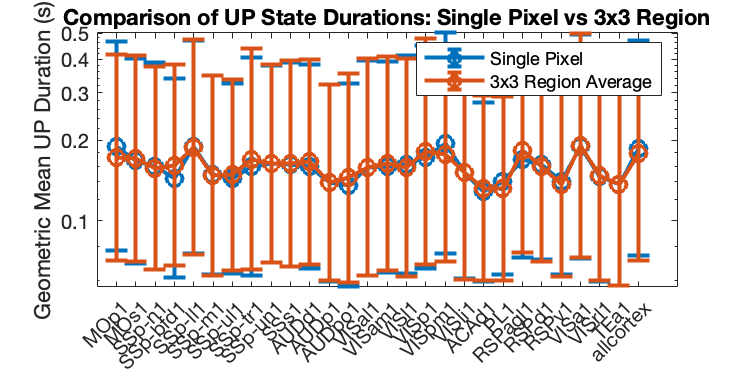

single_upMean = [];
region_upMean = [];
single_upStd = [];  
region_upStd = [];  
single_sem = [];
region_sem = [];

for i=1:length(labels)
    regionName = labels{i};
    sanitizedRegionName = strrep(regionName, '-', '_');
    
    % For single pixel - calculate in log space
    up_data = single_upDurations.(sanitizedRegionName);
    valid_data = up_data(up_data > 0);  % Remove zeros
    log_data = log10(valid_data);
    
    % Geometric mean = exp(mean(log(x)))
    geo_mean_one = 10^mean(log_data);
    log_std_one = std(log_data);  % Standard deviation in log space
    sem_one = log_std_one / sqrt(length(log_data)); 

    % For 3x3 region
    up_nine_data = region_upDurations.(sanitizedRegionName);
    combined_data = vertcat(up_nine_data{:}); 
    valid_nine_data = combined_data(combined_data > 0);
    log_nine_data = log10(valid_nine_data);
    
    geo_mean_nine = 10^mean(log_nine_data);
    log_std_nine = std(log_nine_data);
    sem_nine = log_std_nine / sqrt(length(log_nine_data));
    
    % Store values
    single_upMean = [single_upMean; geo_mean_one];
    region_upMean = [region_upMean; geo_mean_nine];
    single_upStd = [single_upStd; log_std_one];
    region_upStd = [region_upStd; log_std_nine];
    single_sem = [single_sem; sem_one];
    region_sem = [region_sem; sem_nine];
end

fig = figure;
% Plot with asymmetric error bars in original scale
errorbar(1:length(labels), single_upMean, ...
         single_upMean - single_upMean./10.^single_upStd, ...  % Lower error
         single_upMean.*10.^single_upStd - single_upMean, ...  % Upper error
         'o-', 'LineWidth', 2, 'MarkerSize', 8, 'CapSize', 10)
hold on;
errorbar(1:length(labels), region_upMean, ...
         region_upMean - region_upMean./10.^region_upStd, ...
         region_upMean.*10.^region_upStd - region_upMean, ...
         'o-', 'LineWidth', 2, 'MarkerSize', 8, 'CapSize', 10)
hold off;

% Set y-axis to log scale
set(gca, 'YScale', 'log')

% Rest of the plotting code remains the same
set(gca, 'XTick', 1:length(labels))
set(gca, 'XTickLabel', labels)
xtickangle(45)
legend('Single Pixel', '3x3 Region Average')
ylabel('Geometric Mean UP Duration (s)')
title('Comparison of UP State Durations: Single Pixel vs 3x3 Region')
set(gcf, 'Position', [100, 100, 1200, 600])

saveDir = fullfile('/Users', 'elisachinigo', 'Documents', 'Widefield_Data');
exportgraphics(fig, fullfile(saveDir, 'UP_durations_region_vs_pixel_SD.pdf'), 'Resolution', 300)

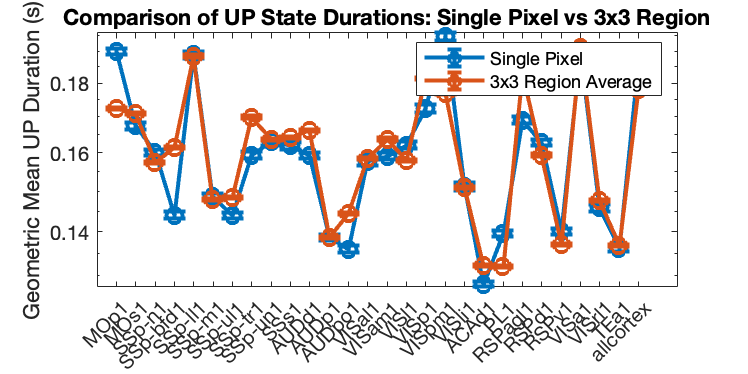



fig = figure;
% Plot with asymmetric error bars in original scale
errorbar(1:length(labels), single_upMean, ...
         single_upMean - single_upMean./10.^single_sem, ...  % Lower error
         single_upMean.*10.^single_sem - single_upMean, ...  % Upper error
         'o-', 'LineWidth', 2, 'MarkerSize', 8, 'CapSize', 10)
hold on;
errorbar(1:length(labels), region_upMean, ...
         region_upMean - region_upMean./10.^region_sem, ...
         region_upMean.*10.^region_sem - region_upMean, ...
         'o-', 'LineWidth', 2, 'MarkerSize', 8, 'CapSize', 10)
hold off;

% Set y-axis to log scale
set(gca, 'YScale', 'log')

% Rest of the plotting code remains the same
set(gca, 'XTick', 1:length(labels))
set(gca, 'XTickLabel', labels)
xtickangle(45)
legend('Single Pixel', '3x3 Region Average')
ylabel('Geometric Mean UP Duration (s)')
title('Comparison of UP State Durations: Single Pixel vs 3x3 Region')
set(gcf, 'Position', [100, 100, 1200, 600])

saveDir = fullfile('/Users', 'elisachinigo', 'Documents', 'Widefield_Data');
exportgraphics(fig, fullfile(saveDir, 'UP_durations_region_vs_pixel_SEM.pdf'), 'Resolution', 300)

figures = [];
% Edges for probability density plots (logarithmic bins in seconds)
edges = 10.^(0:0.1:8) / 1000;
upDownDurations = struct();

for i = 1:length(labels)
    regionName = labels{i};
    sanitizedRegionName = strrep(regionName, '-', '_');
    
    if isfield(upDurations, sanitizedRegionName) && isfield(downDurations, sanitizedRegionName)
        % Get cell arrays containing durations for each pixel
        UPdur = upDurations.(sanitizedRegionName);
        DOWNdur = downDurations.(sanitizedRegionName);
        
        
        if ~isempty(UPdur) && ~isempty(DOWNdur)
            fig = figure('Name', ['Region: ', regionName], 'NumberTitle', 'off', 'Color', 'w', 'Position', [100, 100, 800, 600]);
            hold on;
            
            % DOWN durations probability density
            [N_down, edges_down] = histcounts(DOWNdur, edges, 'Normalization', 'probability');
            histogram('BinEdges', edges_down, 'BinCounts', N_down, 'Normalization', 'probability', ...
                'FaceColor', 'r', 'EdgeColor', 'r', 'FaceAlpha', 0.5, 'DisplayName', 'DOWN durations');
            
            % UP durations probability density
            [N_up, edges_up] = histcounts(UPdur, edges, 'Normalization', 'probability');
            histogram('BinEdges', edges_up, 'BinCounts', N_up, 'Normalization', 'probability', ...
                'FaceColor', 'b', 'EdgeColor', 'b', 'FaceAlpha', 0.5, 'DisplayName', 'UP durations');
            
            % Plot mean and median lines
            xline(mean(DOWNdur), '--r', 'LineWidth', 1.5, 'DisplayName', ['DOWN Mean (' num2str(mean(DOWNdur), '%.2f') 's)']);
            xline(median(DOWNdur), ':r', 'LineWidth', 1.5, 'DisplayName', ['DOWN Median (' num2str(median(DOWNdur), '%.2f') 's)']);
            xline(mean(UPdur), '--b', 'LineWidth', 1.5, 'DisplayName', ['UP Mean (' num2str(mean(UPdur), '%.2f') 's)']);
            xline(median(UPdur), ':b', 'LineWidth', 1.5, 'DisplayName', ['UP Median (' num2str(median(UPdur), '%.2f') 's)']);
            
            title(['UP and DOWN State Durations for Region ', regionName, ' (Pooled from 3x3 region)'], 'FontSize', 14, 'FontWeight', 'bold');
            xlabel('Duration (s)', 'FontSize', 12);
            ylabel('Probability Density', 'FontSize', 12);
            
            % x-axis to logarithmic scale
            set(gca, 'XScale', 'log');
            xlim([0.01, 100]);
            xticks([0.01, 0.1, 1, 10, 100]);
            xticklabels({'0.01', '0.1', '1', '10', '100'});
            grid on;
            legend('show', 'Location', 'northeast');
            hold off;
            
            % Store pooled durations
            upDownDurations.(sanitizedRegionName).UP = UPdur;
            upDownDurations.(sanitizedRegionName).DOWN = DOWNdur;
            figures = [figures, fig];
        end
    end
end

% Export all figures to a single PDF
% if ~isempty(figures)
%     for i = 1:length(figures)
%         exportgraphics(figures(i), outputFile, 'Append', true);
%         disp(['Figure for Region ' labels{i} ' saved to PDF.']);
%     end
% end

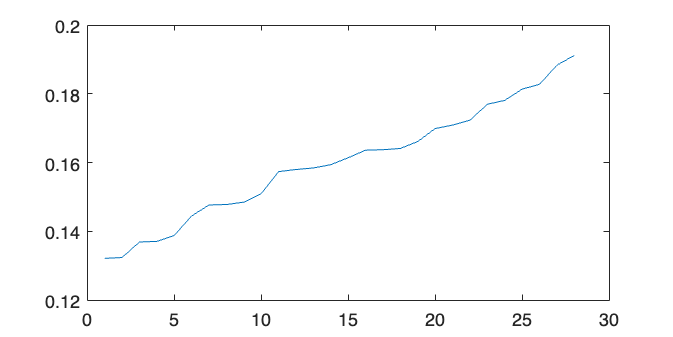

plot(sort(region_upMean))